chimp = getgenbank('NC_001643','SequenceOnly',true);

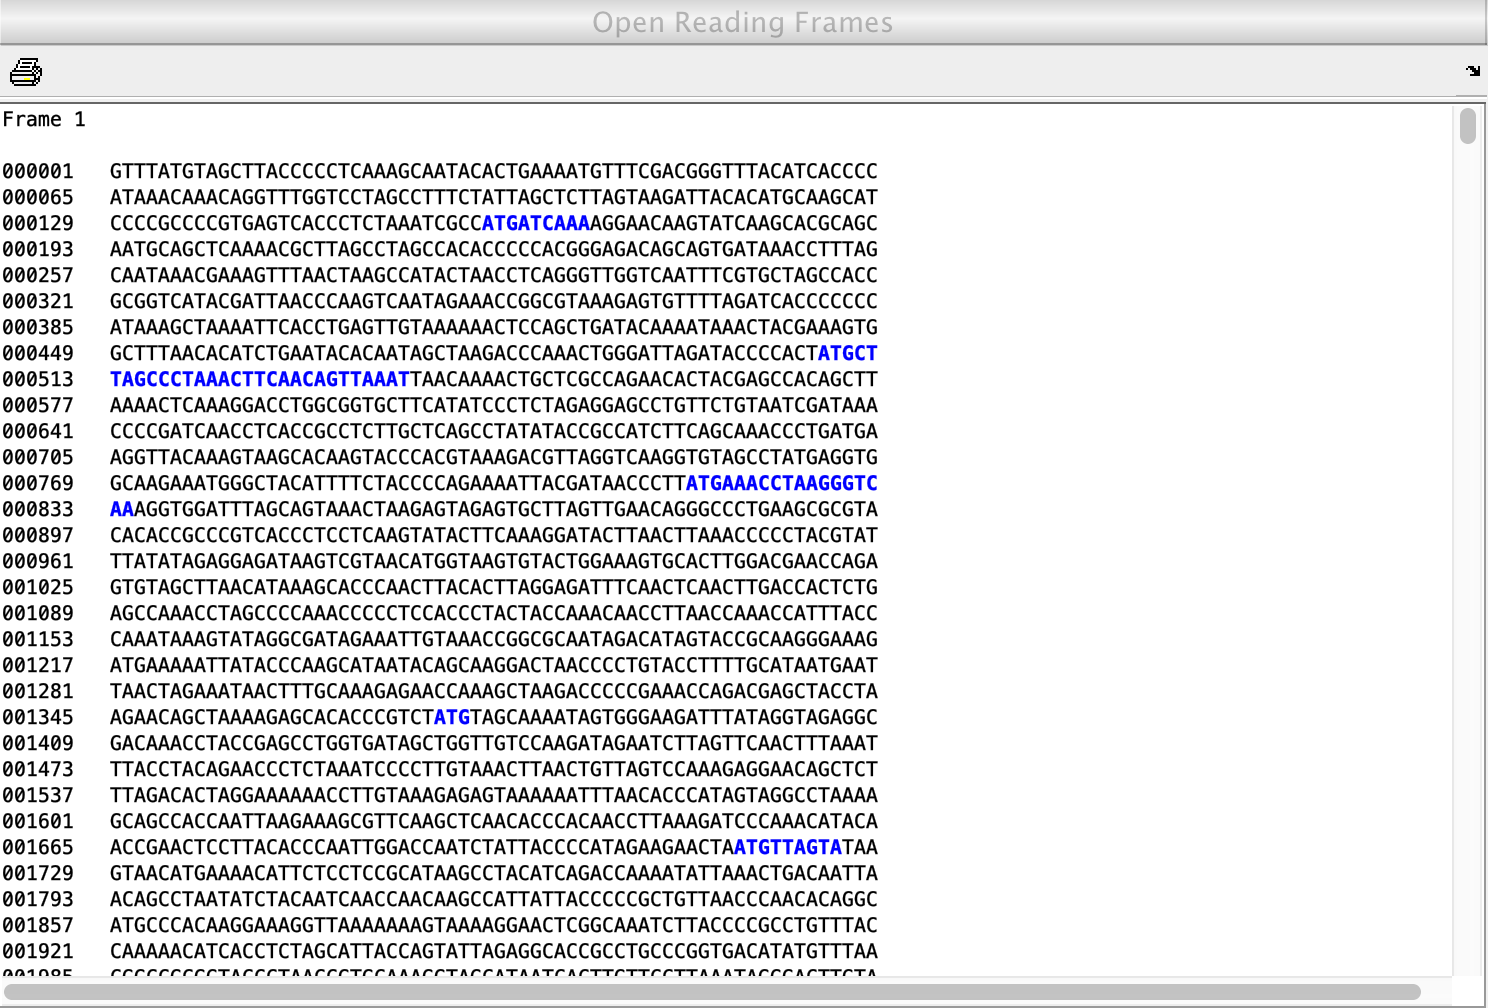

orf = seqshoworfs(chimp,'MINIMUMLENGTH',1, 'geneticcode',2,'frames','all');

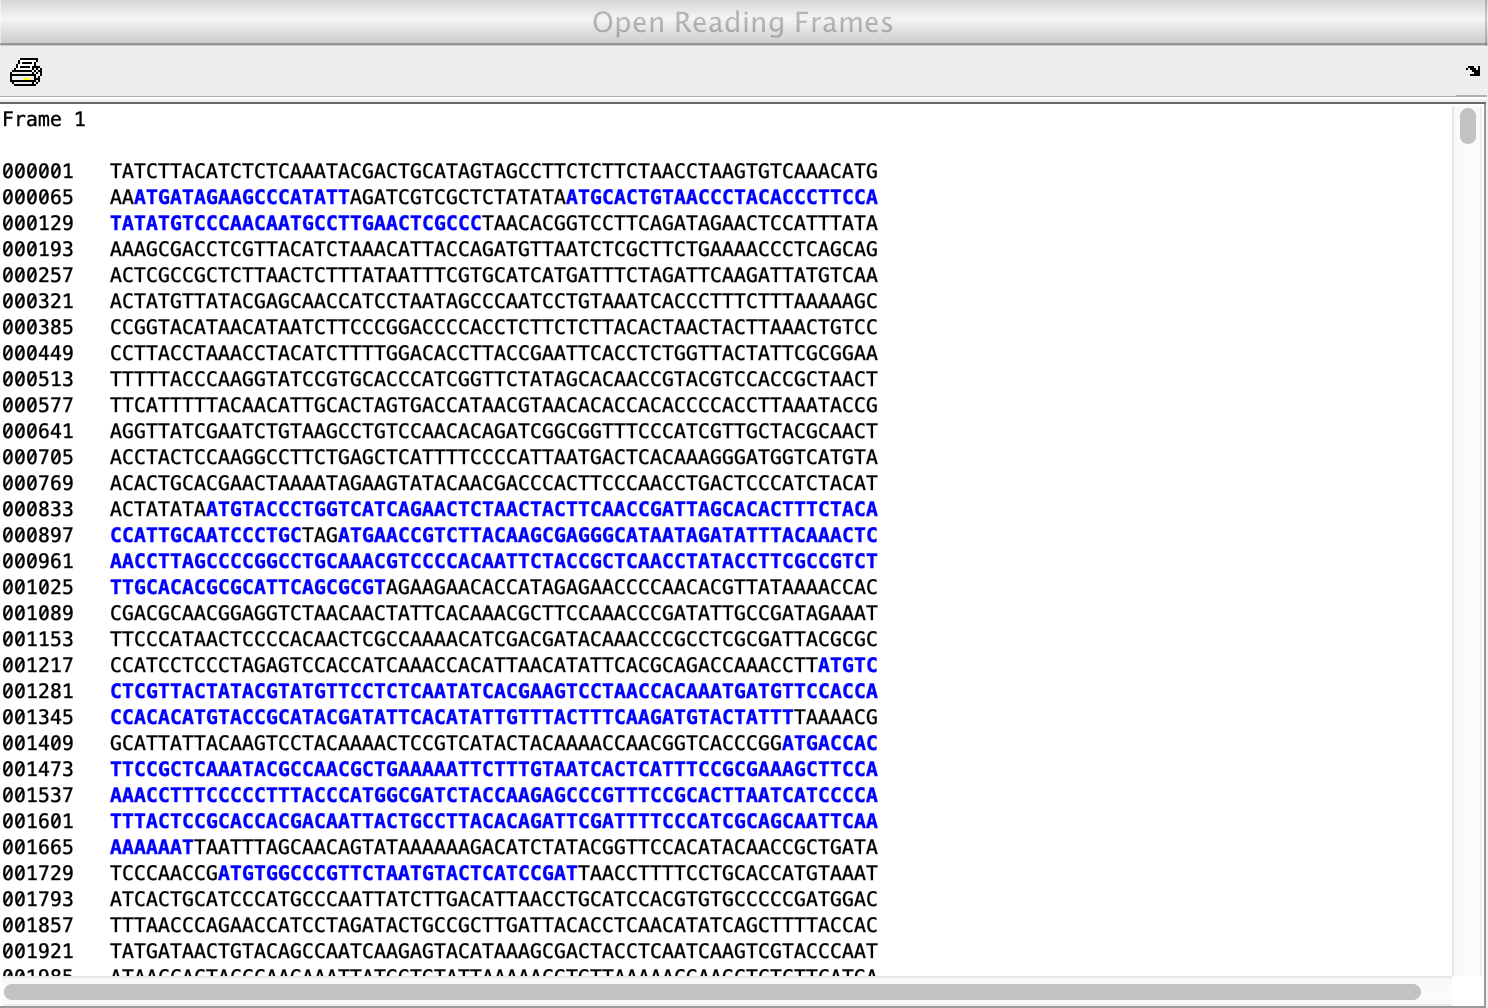

orf1= seqshoworfs(chimp(randperm(length(chimp))),'MINIMUMLENGTH',1,'geneticcode',2,'frames','all');

ORFLength=[];

for i=1:6
   for j=1:length(orf(i).Stop)
    ORFLength=[ORFLength; orf(i).Stop(j)+2 - orf(i).Start(j)];
   end
end

length(ORFLength)

ans = 432

ORFLength1=[];
maxOrfLength = [];
for k=1:100
    orf1= seqshoworfs(chimp(randperm(length(chimp))),'MINIMUMLENGTH',1,'geneticcode',2,'frames','all','nodisplay','true');
    for i=1:6
       for j=1:length(orf1(i).Stop)
        ORFLength1=[ORFLength1; orf1(i).Stop(j)+2 - orf1(i).Start(j)];
       end
    end
    maxOrfLength=[maxOrfLength;max(ORFLength1)];
end
max_threshold=max(maxOrfLength)

max_threshold = 653

max_threshold * 0.95

ans = 620.3500

n_max=length(find(ORFLength >= (max_threshold * 0.95)))

n_max = 9

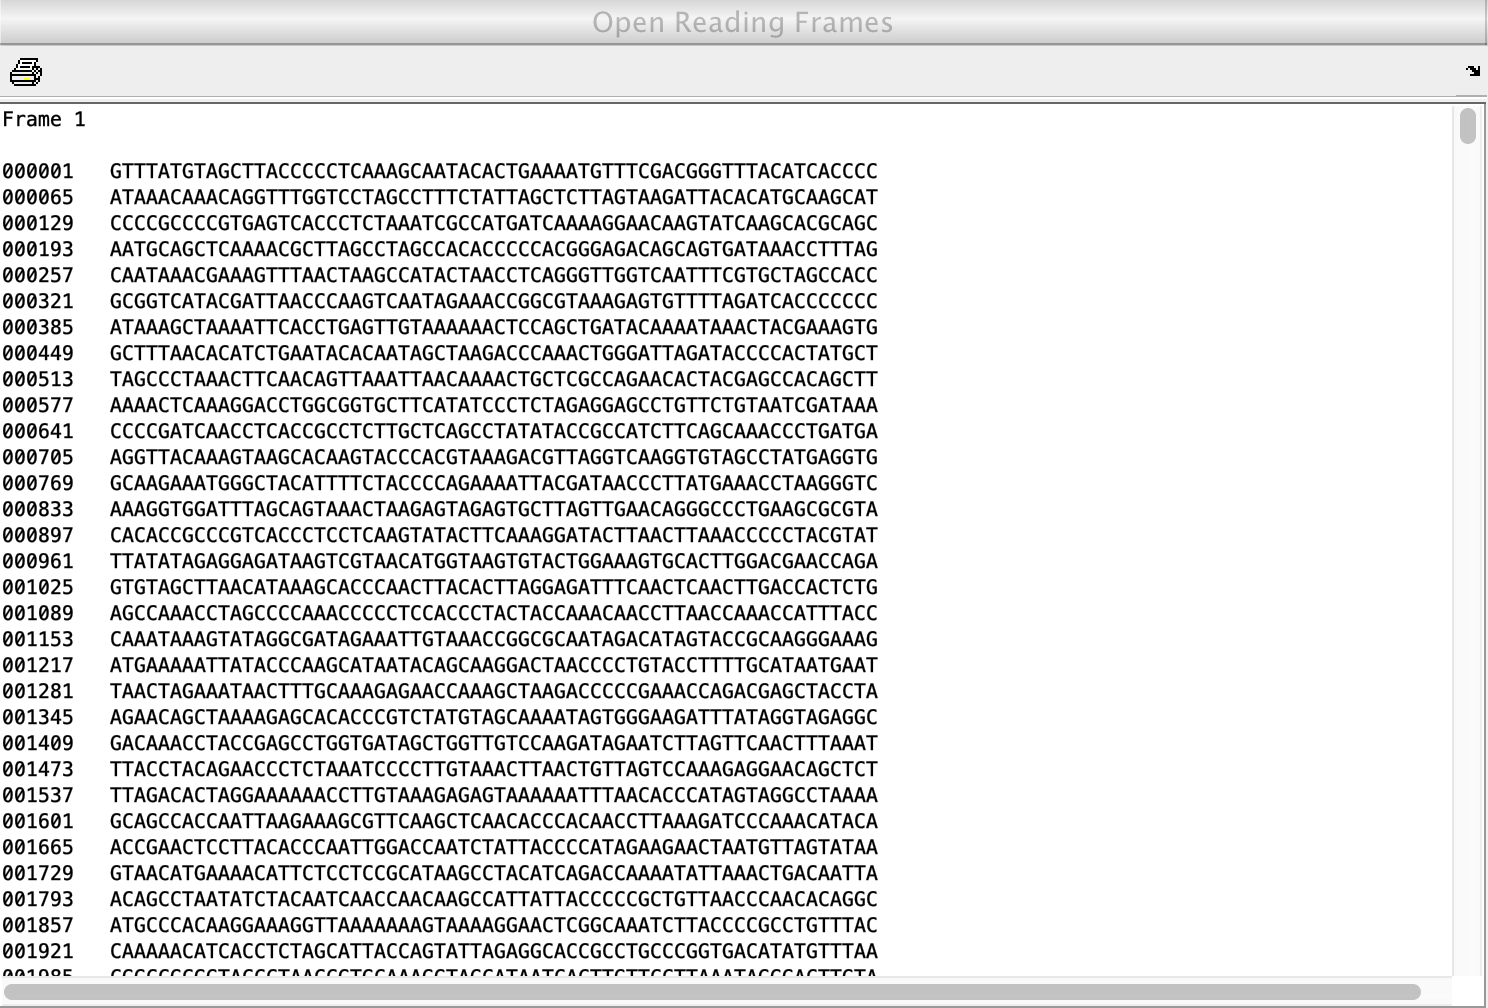

orf_threshold = seqshoworfs(chimp,'MINIMUMLENGTH',max_threshold/3, 'geneticcode',2,'frames','all');

orfNew=[];
for i=1:6
    for j=1:length(orf_threshold(i).Stop)
        orfNew=[orfNew; orf_threshold(i).Stop(j)+2 - orf_threshold(i).Start(j)];
    end
end
length(orfNew)

ans = 9

codons=[];
aminoacid=[];
for i=1:6
    for j= 1:length(orf_threshold(i).Stop)
        proteinSeq = chimp(orf_threshold(i).Start(j):orf_threshold(i).Stop(j)+2);
        codons= [codons; string(proteinSeq),orf_threshold(i).Start(j),orf_threshold(i).Stop(j)+2];
        aminoacid = [aminoacid; string(nt2aa(proteinSeq, 'geneticcode',2)),orf_threshold(i).Start(j),orf_threshold(i).Stop(j)+2];
    end
end
length(codons)

ans = 9

length(aminoacid)

ans = 9